#     Landmark localization 2d

Simulation of a robot moving in a 2d plane. Measurements are taken by beacons ( which transmit the range back to the robot ) and other sensors.

Date Started : 13 Dec. 2023 , 4: 30 PM

Author : Giorgio Ridolfi

## Sources in consultation order

1) [https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine](https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine)

2) [https://undocumentedmatlab.com/](https://undocumentedmatlab.com/)

3) Ristic, Branko, Sanjeev Arulampalam, and Neil Gordon. Beyond the Kalman filter: Particle filters for tracking applications. Artech house, 2003.

4) [https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8](https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8)

5) Groves, P. D. (2015). Principles of GNSS, inertial, and multisensor integrated navigation systems, [Book review]. *IEEE Aerospace and Electronic Systems Magazine*, *30*(2), 26-27.

6) [https://www.youtube.com/watch?v=5Pu558YtjYM&list=PLgnQpQtFTOGQrZ4O5QzbIHgl3b1JHimN_&index=4](https://www.youtube.com/watch?v=5Pu558YtjYM&list=PLgnQpQtFTOGQrZ4O5QzbIHgl3b1JHimN_&index=4)

## System Info

close all
clc
display("OS : " + computer("arch") + ", " + feature('GetOS') )

    "OS : glnxa64, Linux 6.5.6-76060506-generic #202310061235~1697396945~22.04~9283e32 SMP PREEMPT_DYNAMIC Sun O x86_64"



display("Processor : " + feature('GetCPU') + ", " + feature('numCores') )

    "Processor : Intel(R) Core(TM) i5-8600K CPU @ 3.60GHz, 6"



% GPU = gpuDevice
clear all


## Generation of poses

We first generate a set of desired poses. From these, we create noisy system inputs to feed our robot by adding gaussian noise to the true inputs. This account for imperfections in the robot's movement. Then we calculate the poses that the robot achieves

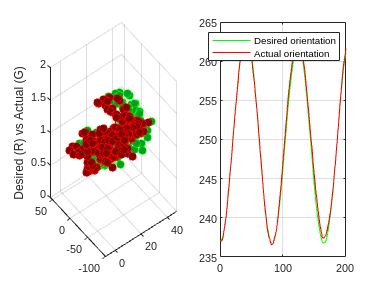

N_poses = 200;
poses = zeros(3,N_poses+1); % x_meters y_meters theta_radians
pose_0 = [ randi(10) ; randi(10) ; randi([0 360])  ];
poses(:,1) = pose_0;
u_odm = zeros(3,N_poses); 
real_poses = zeros(3,N_poses+1); 
real_poses( : , 1 ) = pose_0;

% Random walk params
stdx = 3;
stdy = 9;
psi_max = 6; % Degrees

stdtr = 0.1;
stdrot = 0.08726646255  ; % 0.01745329251*5


for i = 1 : N_poses

 x_incr = stdx*randn() ;
 y_incr = stdy*randn();
 psi_incr = sin(i*0.076) + 0.01745329251*randi([-psi_max psi_max]);

 poses(:,i+1) = poses(:,i) +  [ x_incr ; y_incr ; psi_incr ] ; 

 transl = sqrt( x_incr*x_incr + y_incr*y_incr ) ;
 rot1 = atan2(y_incr,x_incr) ;
 rot2 = poses(3,i+1) - poses(3,i) - rot1 ;
 
 u_odm(:,i) = [ transl + stdtr*randn()  ; rot1  + stdrot*randn() ; rot2 + stdrot*randn()   ];


 real_poses(3,i+1) = real_poses(3,i) + u_odm(2,i);
 real_poses(1,i+1) = real_poses(1,i) + u_odm(1,i)*cos( u_odm(2,i) );
 real_poses(2,i+1) = real_poses(2,i) + u_odm(1,i)*sin( u_odm(2,i) );
 real_poses(3,i+1) = real_poses(3,i+1) + u_odm(3,i) ;

end


figure
subplot(1,2,1);
plot3( poses(1,:), poses(2,:) , ones(1,N_poses+1) , '-o','Color','green','MarkerSize',6,'MarkerFaceColor','#049E22')
hold on
grid on
plot3(real_poses(1,:) , real_poses(2,:) , ones(1,N_poses+1) , '-o','Color','r','MarkerSize',6, 'MarkerFaceColor','#7D0503' )
zlabel("Desired (R) vs Actual (G)")

subplot(1,2,2);
plot(poses(3,:) , 'green' )
hold on
plot(real_poses(3,:) ,'red' )
grid on
legend("Desired orientation" , "Actual orientation")

The robot achieves the poses through a reasonably smooth trajectory. First, upsample.

N_up = 100;
dT = 1/N_up;
poses_up = zeros(3,N_up*N_poses);
slider = 0;
for i = 1 : N_poses
    for j = 1 : N_up
        alpha = j/N_up; 
        poses_up(:,j+slider) = (1-alpha)*real_poses(:,i) + (alpha)*real_poses(:,i+1);
    end
    slider = slider + 100;
end

figure
subplot(1,2,1);
plot3( poses_up(1,:), poses_up(2,:) , ones(1,N_up*N_poses) , '-o','Color','green','MarkerSize',2,'MarkerFaceColor','#049E22')
grid on
zlabel("Upsampled trajectory")
hold on

The trajectory will still look reasonably choppy, so we smooth it.

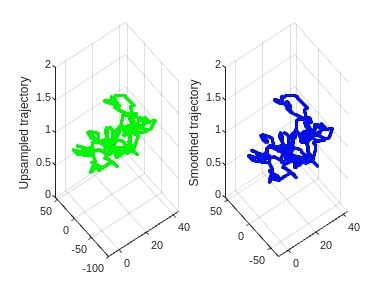

poses_up = kolmogorovZurbenkoFilter( poses_up , 35 , 3 , 1) ;
subplot(1,2,2);
plot3( poses_up(1,:), poses_up(2,:) , ones(1,N_up*N_poses) , '-o','Color','blue','MarkerSize',2,'MarkerFaceColor','#049E22')
grid on
zlabel( "Smoothed trajectory")


clear N_poses poses real_poses u_odm stdx stdy psi_max x_incr y_incr psi_incr i transl rot1 rot2 slider alpha j N_up

N = length(poses_up);

## Generation of a groundtruth

State space of the robot will be x y psi vx vy wpsi. We want to estimate that using Least Squares. The Kalman Filter achieves Recursive Least Squares.

C_b_i = zeros(2,2,N);
z_lq = zeros(3,N);
for i = 1 : N-1
    psi = poses_up(3,i);
    cpsi = cos(psi);
    spsi = sin(psi);
    C_b_i( :,:,i ) = [cpsi , spsi; spsi, cpsi];
    z_lq(:,i) = poses_up(:,i+1) - poses_up(:,i);
end
x_lq = zeros(5,N); % vx vy ax ay wpsi in the body frame
P_lq = 100*ones(5,5,N);

F_lq = eye(5); % Least squares can be applied to static parameters
Q_lq = 0.0001*eye(5); 
R_lq = 0.0001*eye(3);
H_lq = zeros(3,5,N);

for j = 1 : 2
    for i = 1 : N-1
        H_lq(:,:,i) = [dT*C_b_i( :,:,i ) , dT*dT*0.5*C_b_i( :,:,i ) , zeros(2,1) ; zeros(1,2) , zeros(1,2) , dT ];
        [ x_lq(:,i+1) , P_lq(:,:,i+1) ] = mykf( F_lq , H_lq(:,:,i) , x_lq(:,i) , P_lq(:,:,i) , 0 , Q_lq , z_lq(:,i) , R_lq );
    
    end
    P_lq(:,:,1) = mean(P_lq,3);
end

x = [ poses_up ; x_lq ] ;

clear  pose_0 i j C_b_i z_lq psi cpsi spsi x_lq P_lq F_lq Q_lq R_lq H_lq 

## Creation of arena

For visual aid

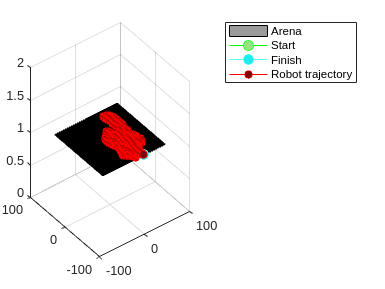


A = [ abs(x(1,:)) ; abs(x(2,:))];
 dim_bound = ceil(max( A , [] , 'all' ));
 x_bounds = [-dim_bound:1:dim_bound];
 y_bounds = [-dim_bound:1:dim_bound];
 index = length(x_bounds);
 z_surf = ones(index);
 
 figure
 surf(x_bounds,y_bounds,z_surf,"FaceColor","#9B9B9B")
 hold on
 plot3(x(1,1) , x(2,1) , 1 , '-o','Color','green','MarkerSize',8, 'MarkerFaceColor','#8EE67F' )
 plot3(x(1,N) , x(2,N) , 1 , '-o','Color','#64FFFD','MarkerSize',8, 'MarkerFaceColor','#1BEDEA' )
 plot3(x(1,:) , x(2,:) , ones(1,N) , '-o','Color','r','MarkerSize',6, 'MarkerFaceColor','#7D0503' )
 legend("Arena" , "Start" ,"Finish", "Robot trajectory" )

## Creation of landmarks

These landmarks transmit range and bearing back to the robot

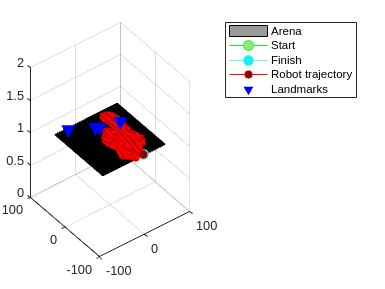

 num_landmarks = 4;
 coord_landmarks = zeros(3, num_landmarks);
for i = 1 : num_landmarks
    x_lm = randi(index);
    y_lm = randi(index);
    coord_landmarks(:,i) = [x_bounds(x_lm) ; y_bounds(y_lm) ; z_surf(y_lm , x_lm)];
end
scatter3(coord_landmarks(1,:) , coord_landmarks(2,:) , coord_landmarks(3,:) , 80 , 'b' , 'filled' , 'v' , 'MarkerEdgeColor','flat' , 'MarkerFaceColor','flat') 
legend("Arena" , "Start" ,"Finish", "Robot trajectory","Landmarks"  )


clear x_lm y_lm x_bounds y_bounds index z_surf 

coord_landmarks

coord_landmarks =      5    44    -1   -41
    36    27    40    65
     1     1     1     1


## Generate sensor data

#### #1 Landmark data

A radar periodically scans in a 360 deg motion ( in discrete increments called "sectors" ) using a radio wave, in a process known as *illumination.* When that radiowave hits something, it get reflected back at the radar, and detected by the receiver. The speed of a radiowave through air is approximately the speed of light, so from the measured roundtrip time we estimate the distance from the radar and the reflecting object.

Most objects produce a reflection, so radar tend to pick-up lots of unwanted noise. Wet surfaces, crystals and metal ( and generally, conductive surfaces ) produce more. This is called *clutter*. The way it's handled is by training a recognizing algorithm, that separates clutter from wanted signal as best as it can. This gives the radar a probabilistic characteristic: our wanted object is either detected, with some probability depending on our algorithm, or it is not.

Oftenmost the object that is being tracked is moving relative to the observer. This phenomena translates to an apparent frequency shift in the receiving wave called *doppler effect*. This has an adverse effect, generally. Some specifically designed radars are instead build with this phenomena in mind, and actually perform best in tracking a moving target.

By knowledge of the current position, radars also provide a measurement of bearing, that is the angle that forms beetween the segment that joins the observer and receiver, and the direction of motion. 

For the purpose of this simplified simulation we will model the adverse effect as additive gaussian noise and assume our classification algorithm is perfect, so P(detection) = 1 

Furthermore, we will assume that measurements are uncorrelated; this is often untrue in practice, given the way that humans build the worls. If a radar sector corresponds to a "hit", it's quite likely the previous or next sector was too.

range = zeros(num_landmarks,N);
bearing = zeros(num_landmarks,N);
stdrange =  1 ;
stdbearing =  1 ;
for i = 1 : N
 for j = 1 : num_landmarks
     [ range(j,i) ,  bearing(j,i) ] = hRadar2D( x(:,i) , coord_landmarks(:,j) ) ;
     range(j,i) = range(j,i) + stdrange*randn();
     bearing(j,i) = bearing(j,i) + stdbearing*randn();
 end
end

#### #2 IMU

IMU are devices that measure specific force and rotational velocity. They suffer from a variety of error sources, and are generally ill-equipped to meet navigation requirements alone for all but the costliest of devices. In two dimensions, we can limit our IMU to two XY accels and one Z gyro

accels = zeros(2,N);
gyro = zeros(1,N);
for i = 1 : N
end


## APPENDIX : Functions

function [range_out , bearing_out ] = hRadar2D(x_in , lm_in)
% Usage: pass position of observer ( as a column vector) and coordinates of landmark ( as a column vector ). Order
% should be XYZ on both
    
    dx = x_in(1) - lm_in(1) ;
    dy = x_in(2) - lm_in(2) ;
    range_out = sqrt( dx*dx + dy*dy  ) ;
    bearing_out = atan2(dy,dx)  ; 

end
